G = get_full_graph(fullfile("additional_Files", "building_collider_list.csv"), true);

folder_path = fullfile("D:\big-data\2025-westbrueck\preprocessing-pipeline\noises-vs-gazes");
p_table = create_participant_table(folder_path);
folder_path = fullfile("D:\big-data\2025-westbrueck\preprocessing-pipeline\graph-saturation");
% hardcoded
excluded_parts = [4004, 4025, 4028, 4011];
query = ~any(p_table.PID == excluded_parts, 2);
clean_p_table = p_table(query, :);

saturation_full_data = get_saturation_data(folder_path, clean_p_table.PID', '_saturation_WB.mat');
saturation_full_data = join(saturation_full_data, clean_p_table);

full_central_parts = clean_p_table.PID(clean_p_table.category == "central");
full_perip_parts = clean_p_table.PID(clean_p_table.category == "peripheral");
full_control_parts = clean_p_table.PID(clean_p_table.category == "control");
parts = [full_control_parts; full_central_parts; full_perip_parts];

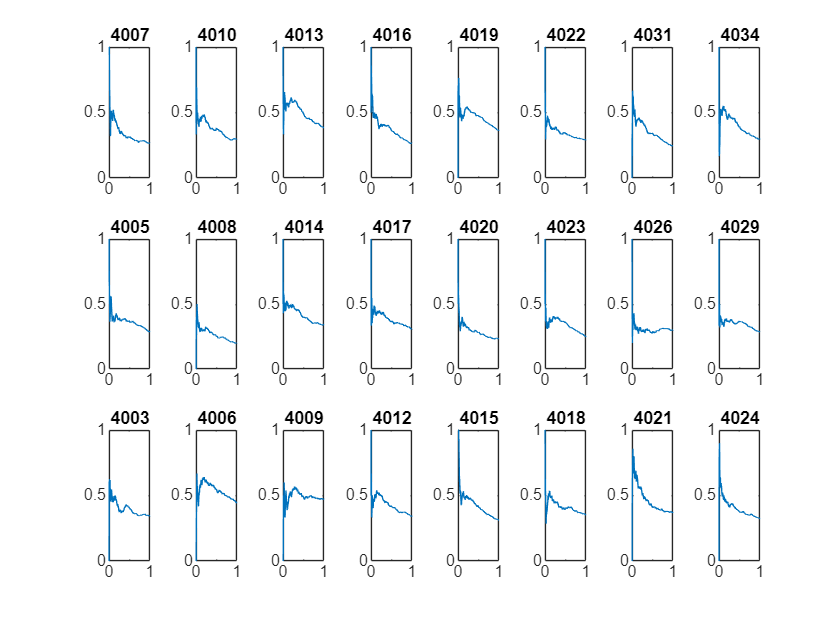

tiledlayout(3, 8);
dummy_table = table();
for dummy_p = parts'
    cur_table = table();
    nexttile;
    cur_data = saturation_full_data(saturation_full_data.PID == dummy_p, :);
    plot(cur_data.time, cur_data.graph_saturation)
    cur_table.saturation = cur_data.graph_saturation(end);
    cur_table.PID = dummy_p;
    hold on
    x = 0:0.01:1;
    plot(0.5, x);
    title(string(dummy_p));
    hold off
    dummy_table = [dummy_table; cur_table];
end

dummy_table = join(dummy_table, clean_p_table);
dummy_table.category = categorical(dummy_table.category);

lm = fitlm(dummy_table, "saturation ~ category");
lm

lm = Linear regression model:
    saturation ~ 1 + category

Estimated Coefficients:
                           Estimate       SE       tStat       pValue  
                           ________    ________    ______    __________

    (Intercept)              0.2747     0.01794    15.312    7.2284e-13
    category_control       0.025948    0.025371    1.0227       0.31807
    category_peripheral    0.094193    0.025371    3.7126     0.0012888


Number of observations: 24, Error degrees of freedom: 21
Root Mean Squared Error: 0.0507
R-squared: 0.412,  Adjusted R-Squared: 0.356
F-statistic vs. constant model: 7.36, p-value = 0.00379

anova(lm)

ans = 2×5 table
                 SumSq      DF     MeanSq        F        pValue  
                ________    __    _________    ______    _________

    category    0.037875     2     0.018937    7.3551    0.0037931
    Error       0.054069    21    0.0025747                       


## Graph Check

Get graphs

Calculate distances

check normal anova in R with lm

query = ~any(p_table.PID == excluded_parts, 2);
clean_p_table = p_table(query, :);
graph_folder_path = fullfile("D:\big-data\2025-westbrueck\preprocessing-pipeline\graphs");
graph_diameter_table = get_distance_graph_data(graph_folder_path, clean_p_table.PID', '_Graph_WB.mat');
graph_diameter_table = join(graph_diameter_table, clean_p_table);


#### Fixation Time filtering

- Fixation time mean (with and without correction)

- Fixation time for landmarks

- Fixation time including inside/outside (with and without correction)

- Number of Fixations

% remove noData newSession NH
% exclude participants
removed_clusters = ["noData", "newSession", "NH"];
query = ~any(string(gaze_full_data.hitObjectColliderName) == removed_clusters, 2);

clean_gaze_full_data = gaze_full_data(query, :);
query = ~any(clean_gaze_full_data.PID == excluded_parts, 2);
clean_gaze_full_data = clean_gaze_full_data(query, :);


% total fixation
no_fixation = groupsummary(clean_gaze_full_data, "PID");

% sum of cluster duration
collider_sum_gaze = groupsummary(clean_gaze_full_data, {'PID', 'hitObjectColliderName'}, 'sum', 'clusterDuration');

query = ~any(collider_sum_gaze.PID == excluded_parts, 2);
excluded_sum_gaze = collider_sum_gaze(query, :);

% only participants in control group
query = any(excluded_sum_gaze.PID == control_parts.PID', 2);
excluded_control_sum_gaze = excluded_sum_gaze(query,:);

% clean gaze data joined with participant table
gaze_full_group = join(clean_gaze_full_data, p_table);
gaze_full_group.category = reordercats(categorical(gaze_full_group.category), ["control", "central", "peripheral"]);
gaze_full_group.hitObjectColliderName = categorical(gaze_full_group.hitObjectColliderName);
gaze_full_group.PID = categorical(gaze_full_group.PID);
gaze_full_group.clusterDuration = gaze_full_group.clusterDuration / 1000;

% custom filter to evaluate gaze
query = gaze_full_group.clusterDuration < 5;
gaze_full_group_cut = gaze_full_group(query, :);

#### Common Building Filter

the buildings that are seen by control participants are considered as common buildings.

common_buildings = G.Nodes.Name;
cur_parts = unique(excluded_control_sum_gaze.PID);

for control = cur_parts'
    query = excluded_control_sum_gaze.PID == control;
    cur_excluded_control_sum_gaze = excluded_control_sum_gaze(query, :)
    cur_buildings = cur_excluded_control_sum_gaze.hitObjectColliderName;
    common_buildings = intersect(common_buildings, cur_buildings);
end

cur_excluded_control_sum_gaze = 77×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4007      {'Building_100'}            8              3008.4       
    4007      {'Building_101'}            9              3387.1       
    4007      {'Building_102'}            3              1501.1       
    4007      {'Building_109'}            1              399.32       
    4007      {'Building_139'}            2              1402.5       
    4007      {'Building_140'}            8              3624.7       
    4007      {'Building_141'}            1               476.5       
    4007      {'Building_144'}            3              1187.6       
    4007      {'Building_145'}           15              7112.5       
    4007      {'Building_146'}         

cur_excluded_control_sum_gaze = 76×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4010      {'Building_100'}           10                5279       
    4010      {'Building_101'}           29               17097       
    4010      {'Building_102'}           12              6676.6       
    4010      {'Building_108'}            1              311.17       
    4010      {'Building_109'}            5                2865       
    4010      {'Building_141'}            2              664.01       
    4010      {'Building_143'}            1              377.74       
    4010      {'Building_144'}            1              420.46       
    4010      {'Building_145'}            6              2794.9       
    4010      {'Building_146'}         

cur_excluded_control_sum_gaze = 85×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4013      {'Building_100'}            9              3424.6       
    4013      {'Building_101'}           15                6104       
    4013      {'Building_102'}            7              3328.5       
    4013      {'Building_137'}            1              433.59       
    4013      {'Building_139'}            4              1404.1       
    4013      {'Building_140'}           12              5363.2       
    4013      {'Building_141'}            3                1634       
    4013      {'Building_142'}            5              1598.1       
    4013      {'Building_143'}            3              1065.7       
    4013      {'Building_144'}         

cur_excluded_control_sum_gaze = 73×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4016      {'Building_100'}           26               11980       
    4016      {'Building_101'}           23               10996       
    4016      {'Building_102'}           37               26767       
    4016      {'Building_140'}            2              866.17       
    4016      {'Building_141'}            4              1956.9       
    4016      {'Building_143'}            1               444.3       
    4016      {'Building_144'}            7              2457.4       
    4016      {'Building_145'}            7              2377.4       
    4016      {'Building_147'}           14              5868.7       
    4016      {'Building_148'}         

cur_excluded_control_sum_gaze = 91×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4019      {'Building_100'}            3              964.94       
    4019      {'Building_101'}            9              4211.4       
    4019      {'Building_102'}            7              3208.2       
    4019      {'Building_103'}            1              410.02       
    4019      {'Building_108'}            1              365.87       
    4019      {'Building_109'}            2              799.38       
    4019      {'Building_139'}            3              1020.8       
    4019      {'Building_140'}            1              556.57       
    4019      {'Building_141'}            6              1812.2       
    4019      {'Building_142'}         

cur_excluded_control_sum_gaze = 86×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4022      {'Building_100'}           15              5258.1       
    4022      {'Building_101'}            8                3455       
    4022      {'Building_102'}           10              4208.6       
    4022      {'Building_103'}            1               410.9       
    4022      {'Building_108'}            1              299.77       
    4022      {'Building_139'}            5                1847       
    4022      {'Building_140'}            5              3420.4       
    4022      {'Building_141'}            4              1514.2       
    4022      {'Building_142'}            1              2294.9       
    4022      {'Building_143'}         

cur_excluded_control_sum_gaze = 80×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4031      {'Building_100'}           12              4479.4       
    4031      {'Building_101'}           17              6876.8       
    4031      {'Building_102'}           12              5948.6       
    4031      {'Building_108'}            1              422.69       
    4031      {'Building_139'}            1              409.97       
    4031      {'Building_140'}            8              4078.6       
    4031      {'Building_141'}            7              3499.7       
    4031      {'Building_143'}            2               844.1       
    4031      {'Building_144'}           15              9043.9       
    4031      {'Building_145'}         

cur_excluded_control_sum_gaze = 82×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4034      {'Building_100'}           10              3598.6       
    4034      {'Building_101'}            6              3432.3       
    4034      {'Building_102'}           12               10551       
    4034      {'Building_131'}            3               890.1       
    4034      {'Building_137'}            1              277.63       
    4034      {'Building_139'}            1              377.34       
    4034      {'Building_140'}            9              4132.8       
    4034      {'Building_141'}            9              5010.2       
    4034      {'Building_142'}            1              656.19       
    4034      {'Building_144'}         

% Common Building := buildings that are seen all of the control
% participants
common_buildings;

query = any(string(excluded_control_sum_gaze.hitObjectColliderName) == string(common_buildings)', 2);
common_buildings_control_sum_gaze = excluded_control_sum_gaze(query, :);

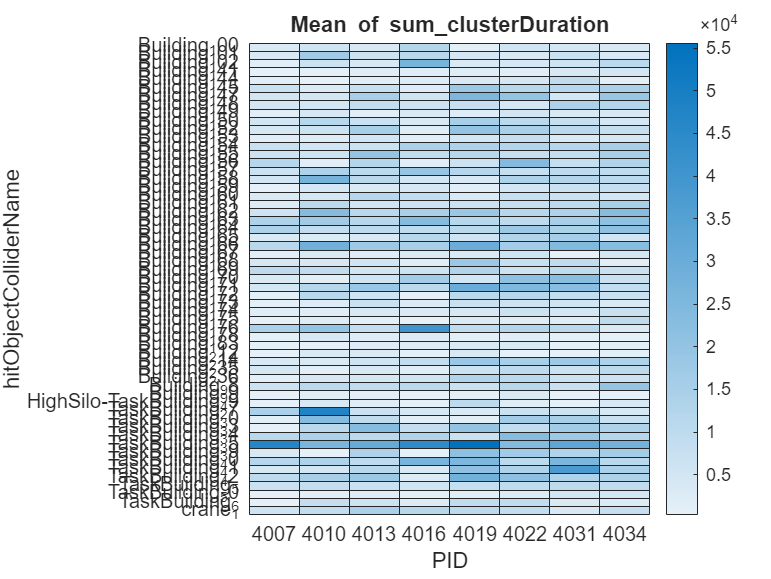

% heatmap of control participants only for sanity check
heatmap(common_buildings_control_sum_gaze, "PID", "hitObjectColliderName", "ColorVariable", "sum_clusterDuration")

% reorder participants to have a good heatmap
unique_parts = unique(excluded_sum_gaze.PID);

full_central_parts = p_table(p_table.category == "central", :);
central_parts = intersect(unique_parts, full_central_parts.PID);

full_perip_parts = p_table(p_table.category == "peripheral", :);
perip_parts = intersect(unique_parts, full_perip_parts.PID);

control_parts = intersect(unique_parts, control_parts.PID);

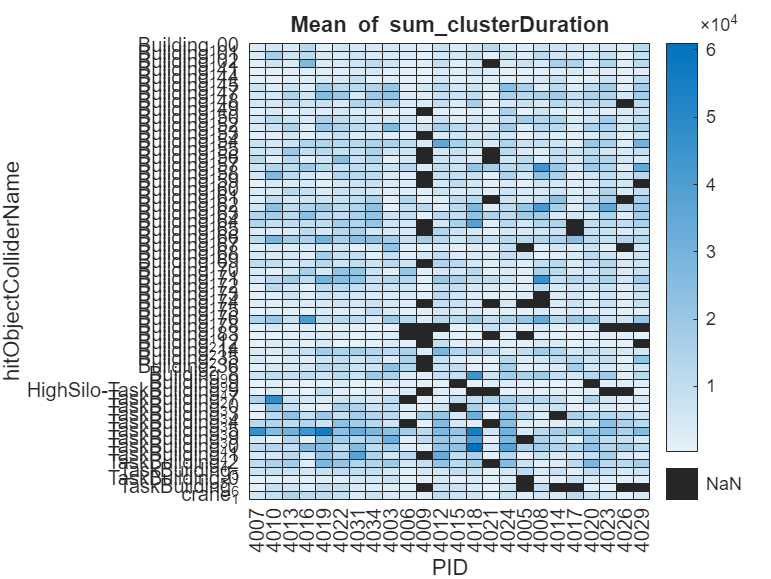

query = any(string(excluded_sum_gaze.hitObjectColliderName) == string(common_buildings)', 2);
commong_buildings_excluded_sum_gaze = excluded_sum_gaze(query, :);
% 
h = heatmap(commong_buildings_excluded_sum_gaze, "PID", "hitObjectColliderName", "ColorVariable", "sum_clusterDuration");
h.XDisplayData = [control_parts; perip_parts; central_parts];

#### Node Data Table

folder_path_sess1 = fullfile("D:\big-data\2025-westbrueck\preprocessing-pipeline\graphs\sess1\");
folder_path_sess2 = fullfile("D:\big-data\2025-westbrueck\preprocessing-pipeline\graphs\sess2\");
folder_path_sess3 = fullfile("D:\big-data\2025-westbrueck\preprocessing-pipeline\graphs\sess3\");
graph_table_sess1 = create_graph_table(folder_path_sess1);
graph_table_sess1.SID = 1 * ones(height(graph_table_sess1), 1);
graph_table_sess2 = create_graph_table(folder_path_sess2);
graph_table_sess2.SID = 2 * ones(height(graph_table_sess1), 1);
graph_table_sess3 = create_graph_table(folder_path_sess3);
graph_table_sess3.SID = 3 * ones(height(graph_table_sess1), 1);
graph_table = [graph_table_sess1; graph_table_sess2; graph_table_sess3];
graph_table.nodes = categorical(string(graph_table.nodes));

node_table = G.Nodes;
node_table.Name = categorical(node_table.Name);
graph_table = join(graph_table, node_table, ...
    "LeftKeys", "nodes", ...
    "RightKeys", "Name", ...
    "RightVariables", "inside");
graph_table = join(graph_table, clean_p_table);

% hardcoded excluded parts defined above
query = ~any(graph_table.PID == excluded_parts, 2);
excluded_graph_table = graph_table(query, :);

% summary connectivity table is the one with full graph to normalize
% everything across all subjects.
summary_connectivity_table = groupsummary(excluded_graph_table, {'PID'}, {'mean', 'std'}, 'connections');

% excluding buildings that are not considered by participants
% the rationale might be that participants are not aware of ROI in the city
% This might lead them to focus on the things by which they already got
% attended.
std_graph_table = excluded_graph_table(excluded_graph_table.connections > 0, :);
standard_summary_connectivity_table = groupsummary(std_graph_table, {'PID'}, {'mean', 'std'}, 'connections');

analyzed_p_data = [control_parts; perip_parts; central_parts];
[r, ~] = find(p_table.PID == analyzed_p_data');
categories = p_table.category(r);

#### Run ANOVA for Connectivity

[r, ~] = find(standard_summary_connectivity_table.PID == analyzed_p_data');

Normality Tests:
Group central: p = 0.3954, Normal
Group control: p = 0.3455, Normal


Group peripheral: p = 0.5000, Normal

Homogeneity of Variance Test:


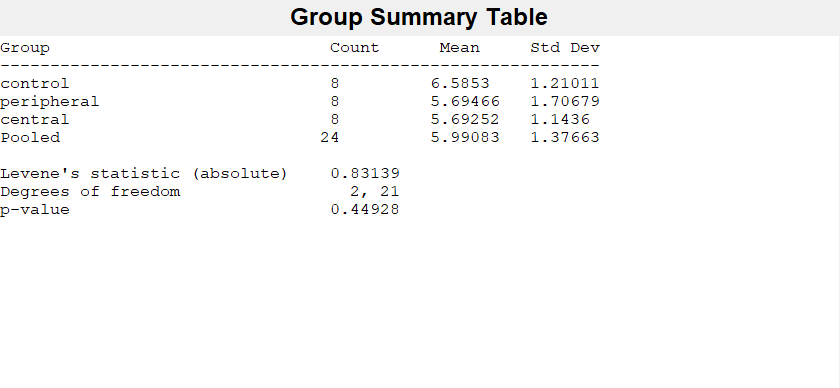

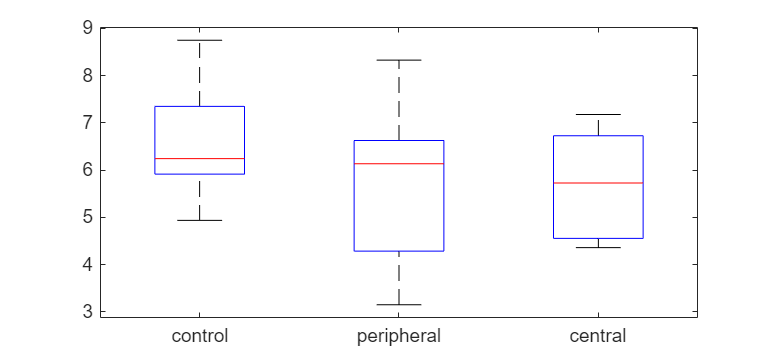

Levene test: p = 0.4493, Equal variances

ANOVA Results:


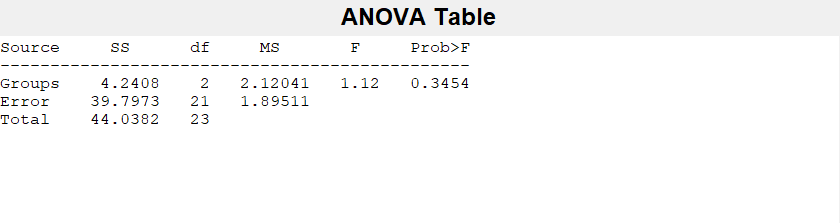

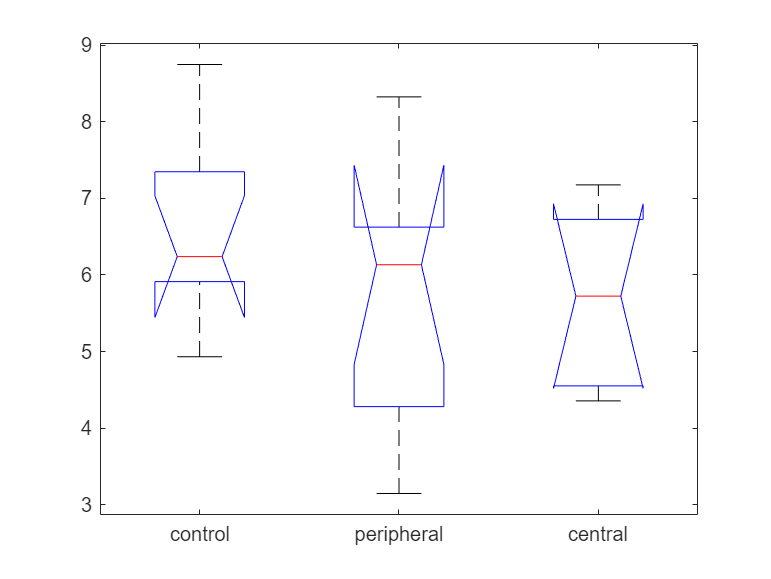

% without correction for mean connections
connectivity_data = standard_summary_connectivity_table.mean_connections(r);
run_anova(connectivity_data, categories);

Normality Tests:
Group central: p = 0.1770, Normal


Group control: p = 0.5000, Normal


Group peripheral: p = 0.5000, Normal

Homogeneity of Variance Test:


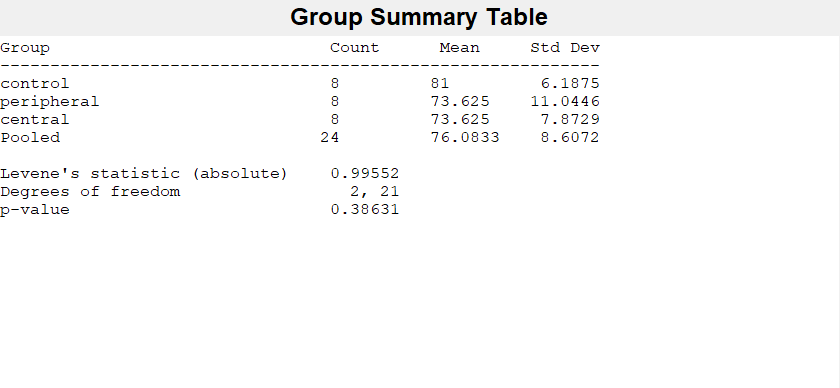

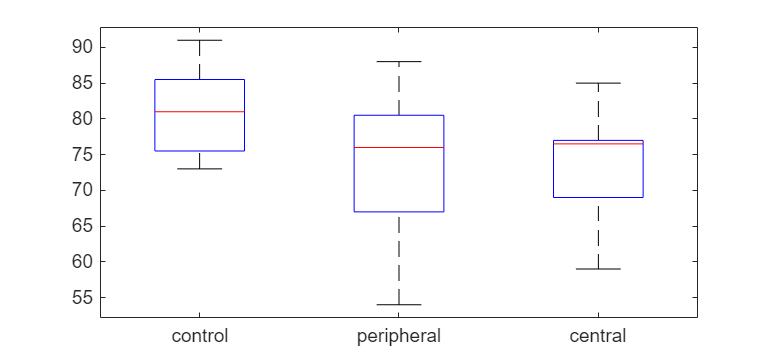

Levene test: p = 0.3863, Equal variances

ANOVA Results:


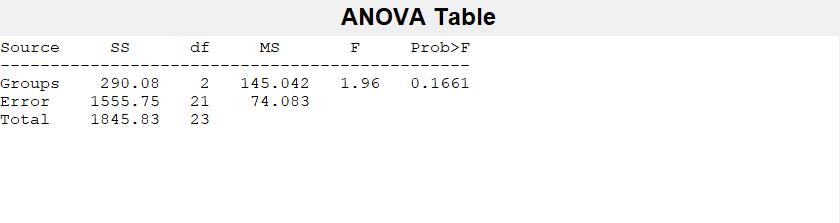

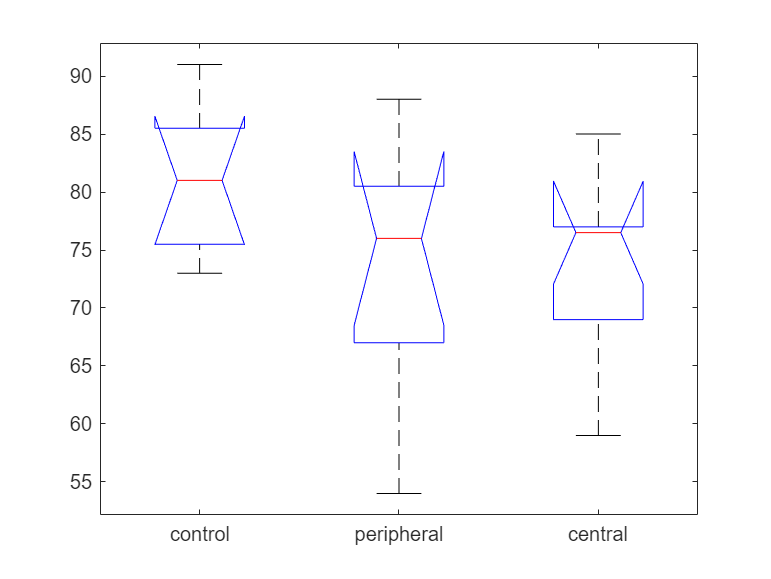

% building count
count_data = standard_summary_connectivity_table.GroupCount(r);
run_anova(count_data, categories);

Normality Tests:


Group central: p = 0.5000, Normal
Group control: p = 0.1046, Normal


Group peripheral: p = 0.5000, Normal

Homogeneity of Variance Test:


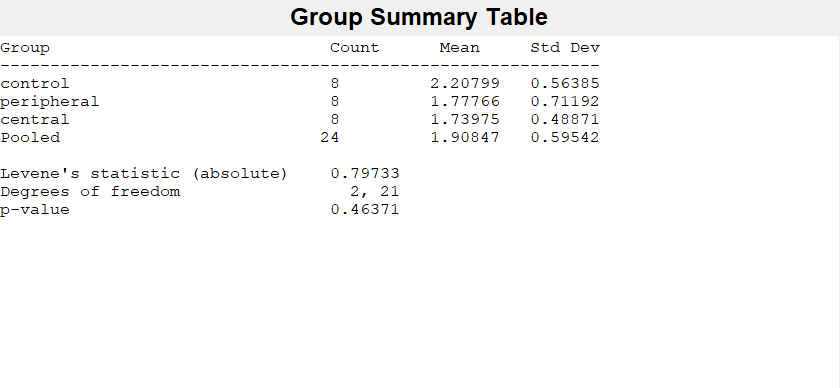

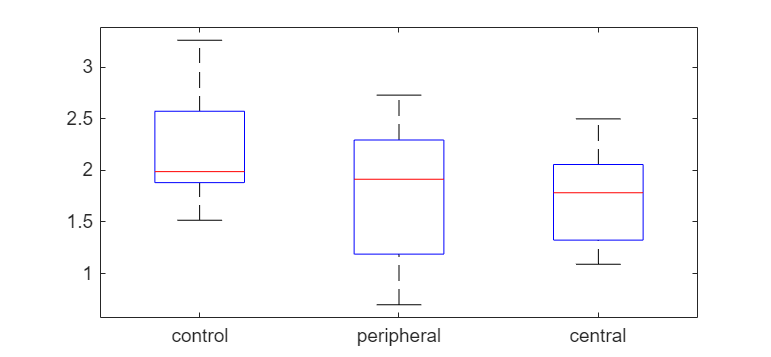

Levene test: p = 0.4637, Equal variances

ANOVA Results:


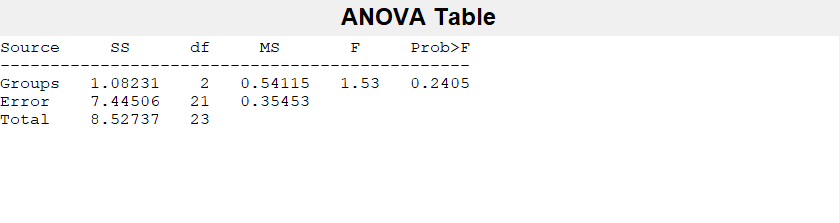

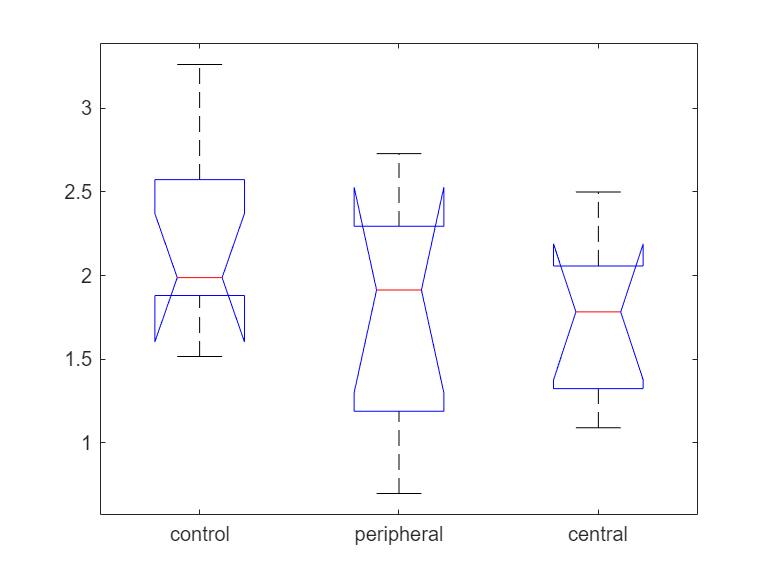

% with correction for mean connections
connectivity_data = summary_connectivity_table.mean_connections(r);
run_anova(connectivity_data, categories);

#### Run ANOVA for Fixation Related Measure

Normality Tests:
Group central: p = 0.0931, Normal


Group control: p = 0.5000, Normal
Group peripheral: p = 0.2969, Normal

Homogeneity of Variance Test:


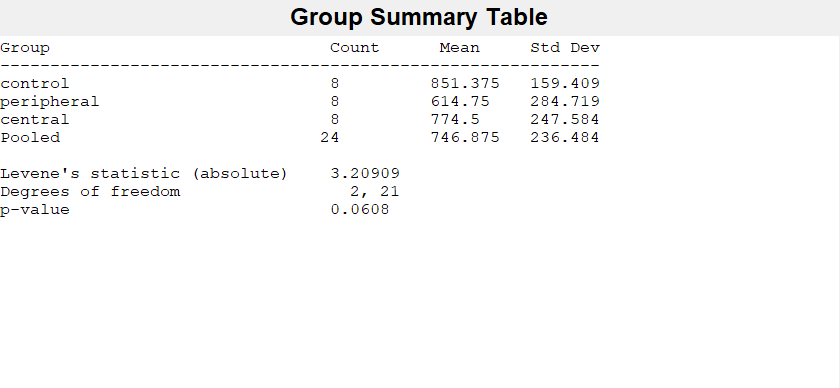

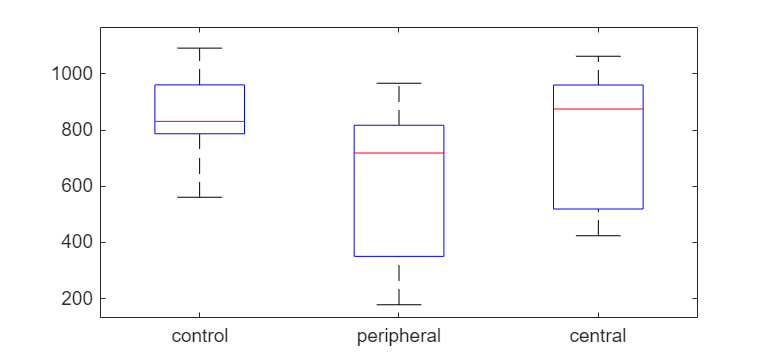

Levene test: p = 0.0608, Equal variances

ANOVA Results:


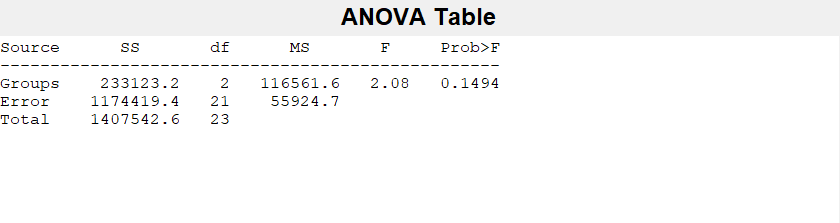

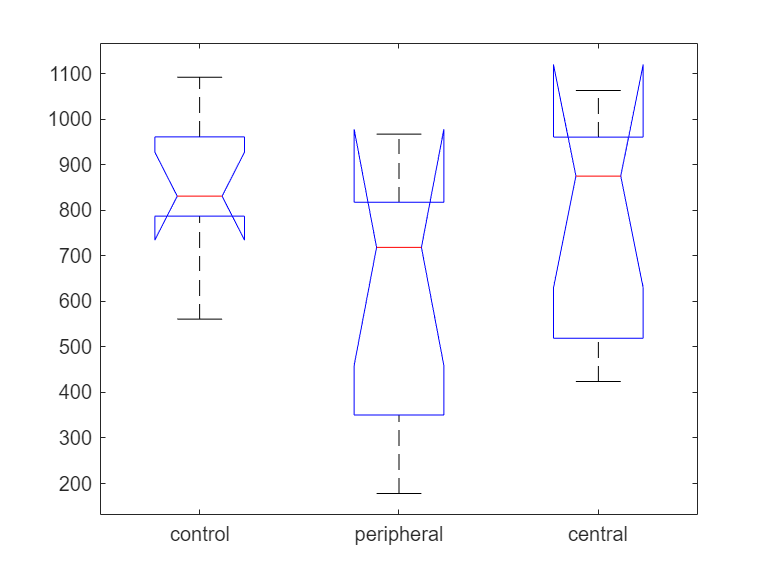

% check # of fixation
[r, ~] = find(no_fixation.PID == analyzed_p_data');

data = no_fixation.GroupCount(r);
run_anova(data, categories);

#### Run GLME for Fixation Data Full (no aggregation)

test_check = run_glme_preliminary_tests( ...
    gaze_full_group, ...
    "clusterDuration", ...
    {"category"}, ...
    "PID" ...
    );

print_struct(test_check);

missing_data             : (table)
has_missing              : false
response_stats           : (struct)
    mean    : 0.691168
    variance: 0.730143
    min     : 0.266607
    max     : 32.2427
is_binary                : false
is_count                 : false
number_of_groups         : 24
min_group_size           : 178
max_group_size           : 1092
mean_group_size          : 746.875
sufficient_groups        : true
recommended_distribution : "gamma"
recommended_link         : "log"
normality_p              : 0.001
is_normal                : false
notes                    : "Non-normal positive data; consider gamma distribution"
recommended_formula      : "clusterDuration  ~  category  + (1| PID )"
total_observations       : 17925
predictors_count         : 1
observations_per_variable: 17925
adequate_sample          : true


% data should be close by, not need to search above
gaze_full_group_median = groupsummary(gaze_full_group, ["PID", "hitObjectColliderName", "category"], "median", "clusterDuration");

[res_full, sum_full] = fit_and_interpret_glme(gaze_full_group_median, "median_clusterDuration ~ category + (1 | PID) + (1 | hitObjectColliderName)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ category + (1 | PID) + (1 | hitObjectColliderName)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 4347.5111, BIC: 4380.5802
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_central: Coefficient = 0.1978 (p=0.0100). Interpret based on link function reciprocal
category_peripheral: Coefficient = -0.3187 (p=0.0000). Interpret based on link function reciprocal


r2 = calculate_nakagawa_r2(res_full);
res_full

res_full = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            1829
    Fixed effects coefficients           3
    Random effects coefficients        151
    Covariance parameters                3
    Distribution                    Gamma 
    Link                            Reciprocal
    FitMethod                       MPL   

Formula:
    median_clusterDuration ~ 1 + category + (1 | PID) + (1 | hitObjectColliderName)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    4347.5    4380.6    -2167.8          4335.5  

Fixed effects coefficients (95% CIs):
    Name                           Estimate    SE          tStat      DF      pValue         Lower       Upper   
    {'(Intercept)'        }          2.2133    0.061902     35.754    1826    1.0978e-212      2.0919      2.3347
    {'category_central'   }         0.19777   


anv = anova(res_full);
anv

anv =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2     pValue     
    {'(Intercept)'}        1278.4    1      1826    1.0978e-212
    {'category'   }        24.227    2      1826     4.1251e-11


disp(anv);


    ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2     pValue     
    {'(Intercept)'}        1278.4    1      1826    1.0978e-212
    {'category'   }        24.227    2      1826     4.1251e-11



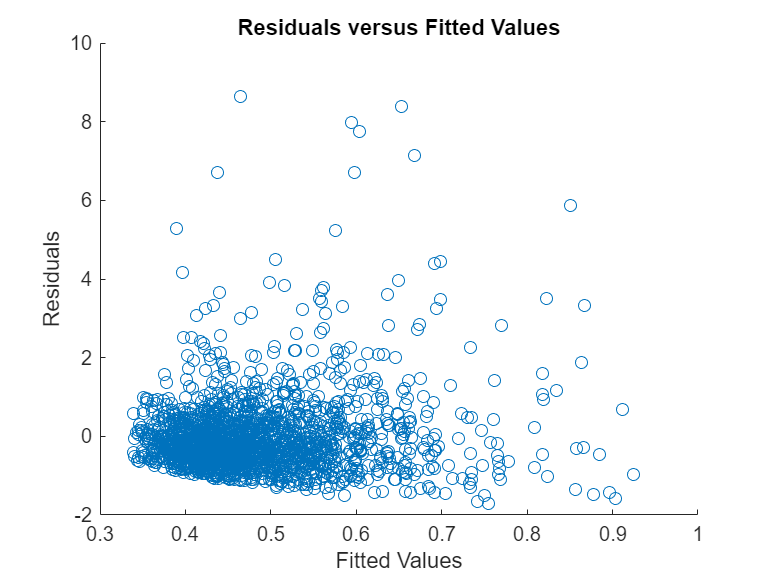

% Residuals
r = residuals(res_full,'ResidualType','Pearson');
mufit = fitted(res_full);
scatter(mufit,r);
title('Residuals versus Fitted Values');
xlabel('Fitted Values');
ylabel('Residuals');

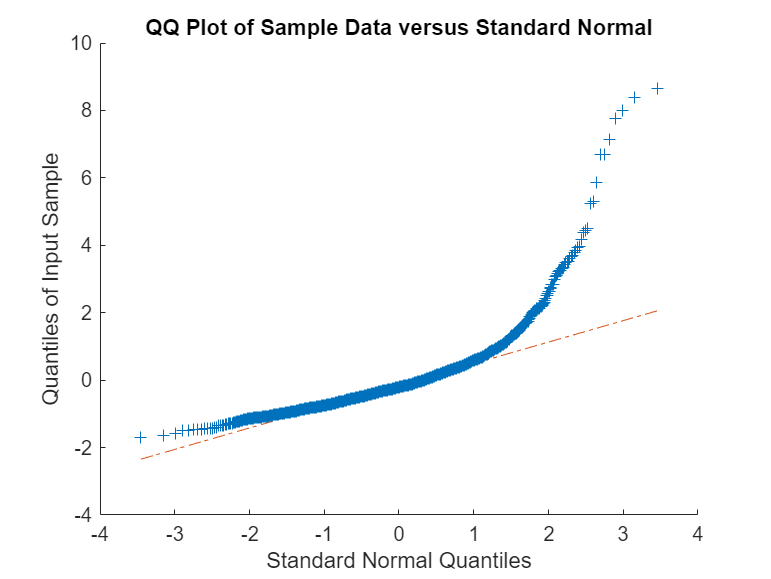

qqplot(r);

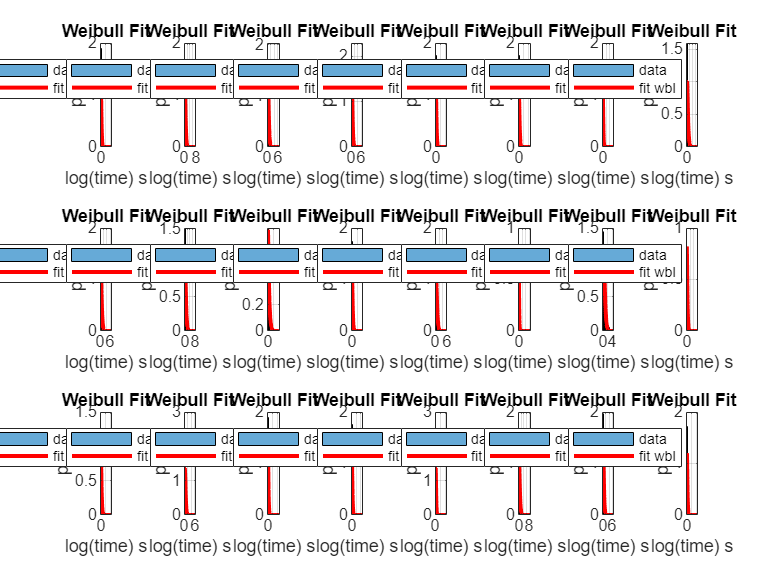


% Check data distribution
% CAUTION: It takes a lot of time to generate as it's vectorized not rasterized.
tiledlayout(3, 8);
for dummy_p = analyzed_p_data'
    nexttile;
    cur_data = gaze_full_group(gaze_full_group.PID == categorical(dummy_p), :);
    fit_normal(cur_data.clusterDuration);
end

#### Run GLME for Fixation Data Sum for Buildings

collider_sum_gaze_p = join(collider_sum_gaze, p_table);
collider_sum_gaze_p.category = reordercats(categorical(collider_sum_gaze_p.category), ["control", "central", "peripheral"]);
collider_sum_gaze_p.hitObjectColliderName = categorical(collider_sum_gaze_p.hitObjectColliderName);
collider_sum_gaze_p.PID = categorical(collider_sum_gaze_p.PID);
collider_sum_gaze_p.sum_clusterDuration = collider_sum_gaze_p.sum_clusterDuration / 1000;

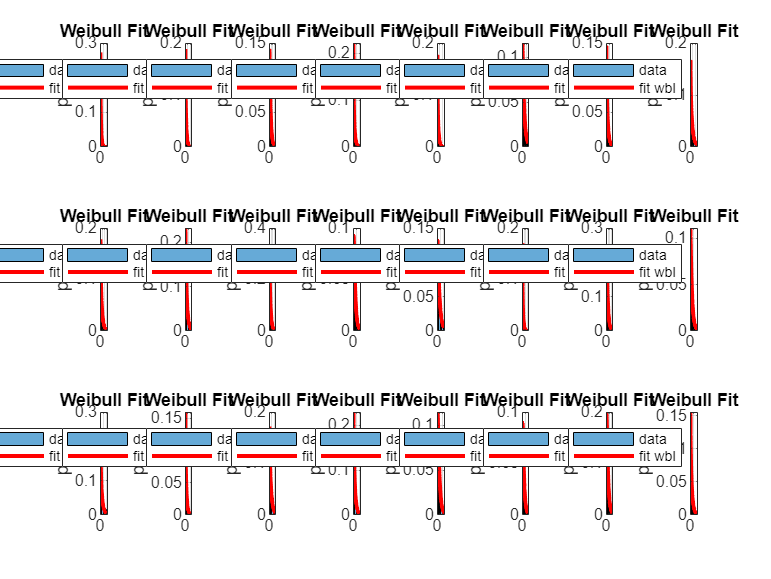

tiledlayout(3, 8);
for dummy_p = analyzed_p_data'
    nexttile;
    cur_data = collider_sum_gaze_p(collider_sum_gaze_p.PID == categorical(dummy_p), :);
    fit_normal(cur_data.sum_clusterDuration);
end

test_check = run_glme_preliminary_tests( ...
    collider_sum_gaze_p, ...
    "sum_clusterDuration", ...
    {"category"}, ...
    "PID" ...
    );

print_struct(test_check);

missing_data             : (table)
has_missing              : false
response_stats           : (struct)
    mean    : 6.77374
    variance: 56.3134
    min     : 0.266676
    max     : 61.0201
is_binary                : false
is_count                 : false
number_of_groups         : 24
min_group_size           : 54
max_group_size           : 91
mean_group_size          : 76.2083
sufficient_groups        : true
recommended_distribution : "gamma"
recommended_link         : "log"
normality_p              : 0.001
is_normal                : false
notes                    : "Non-normal positive data; consider gamma distribution"
recommended_formula      : "sum_clusterDuration  ~  category  + (1| PID )"
total_observations       : 1829
predictors_count         : 1
observations_per_variable: 1829
adequate_sample          : true


[res_full, sum_full] = fit_and_interpret_glme(collider_sum_gaze_p, "sum_clusterDuration ~ category + (1 | PID) + (1 | hitObjectColliderName)", "gamma");

=== Model Summary ===
    "Formula: "    "sum_clusterDuration ~ category + (1 | PID) + (1 | hitObjectColliderName)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: -1078.5173, BIC: -1045.4481
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_central: Coefficient = 0.0127 (p=0.0127). Interpret based on link function reciprocal
category_peripheral: Coefficient = 0.0114 (p=0.0240). Interpret based on link function reciprocal


r2 = calculate_nakagawa_r2(res_full);
res_full

res_full = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            1829
    Fixed effects coefficients           3
    Random effects coefficients        151
    Covariance parameters                3
    Distribution                    Gamma 
    Link                            Reciprocal
    FitMethod                       MPL   

Formula:
    sum_clusterDuration ~ 1 + category + (1 | PID) + (1 | hitObjectColliderName)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -1078.5    -1045.4    545.26           -1090.5 

Fixed effects coefficients (95% CIs):
    Name                           Estimate    SE           tStat     DF      pValue        Lower        Upper   
    {'(Intercept)'        }         0.53974     0.045658    11.821    1826    4.0053e-31      0.45019     0.62928
    {'category_central'   }         0.01265  

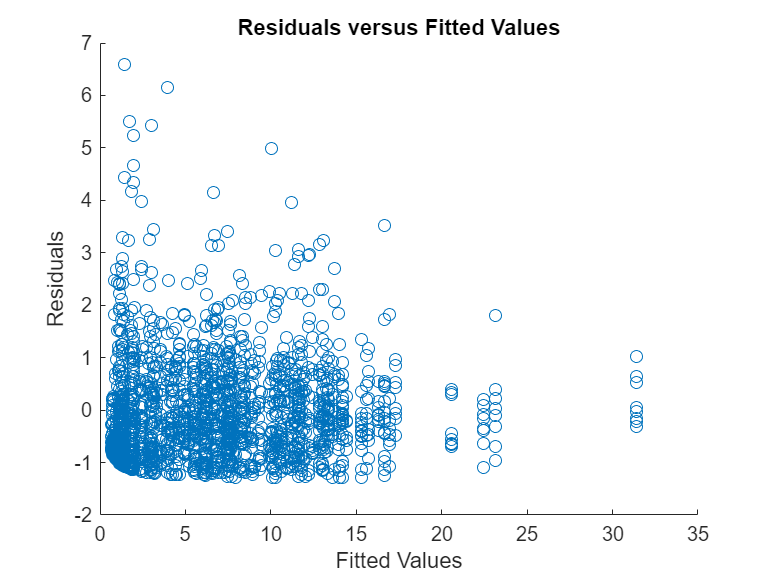

% Residuals
r = residuals(res_full,'ResidualType','Pearson');
mufit = fitted(res_full);
figure;
scatter(mufit,r);
title('Residuals versus Fitted Values');
xlabel('Fitted Values');
ylabel('Residuals');

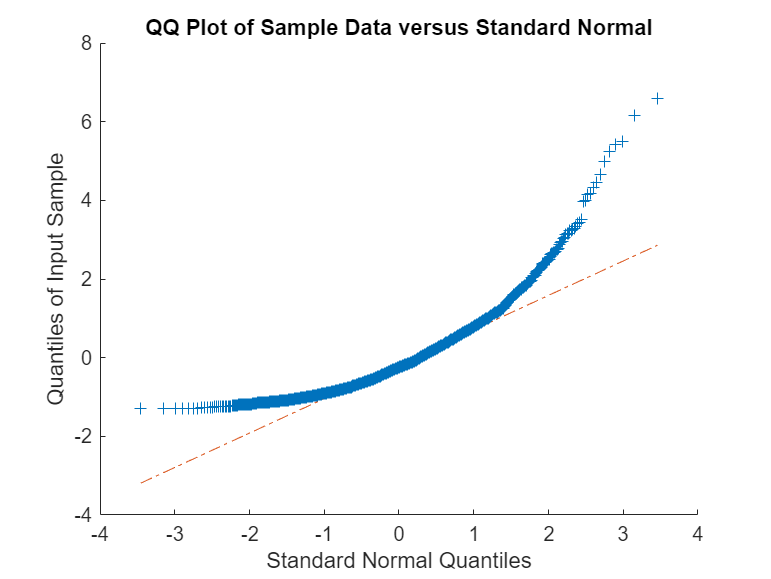

qqplot(r);

#### Run GLME for Fixation Data and the Sum for Buildings with inside/outside

node_table = G.Nodes;
node_table.Name = categorical(node_table.Name);
gaze_full_group_io_building = join(gaze_full_group, node_table, ...
    "LeftKeys", "hitObjectColliderName", ...
    "RightKeys", "Name", ...
    "RightVariables", "inside");

test_check = run_glme_preliminary_tests( ...
    gaze_full_group_io_building, ...
    "clusterDuration", ...
    {"inside"}, ...
    "PID" ...
    );

print_struct(test_check);

missing_data             : (table)
has_missing              : false
response_stats           : (struct)
    mean    : 0.691168
    variance: 0.730143
    min     : 0.266607
    max     : 32.2427
is_binary                : false
is_count                 : false
number_of_groups         : 24
min_group_size           : 178
max_group_size           : 1092
mean_group_size          : 746.875
sufficient_groups        : true
recommended_distribution : "gamma"
recommended_link         : "log"
normality_p              : 0.001
is_normal                : false
notes                    : "Non-normal positive data; consider gamma distribution"
recommended_formula      : "clusterDuration  ~  inside  + (1| PID )"
total_observations       : 17925
predictors_count         : 1
observations_per_variable: 17925
adequate_sample          : true


median_gaze_full_group_io_building = groupsummary(gaze_full_group_io_building, ...
    ["PID", "hitObjectColliderName", "category", "inside"], ...
    "median", ...
    "clusterDuration");
[res_full, sum_full] = fit_and_interpret_glme(median_gaze_full_group_io_building, "median_clusterDuration ~ category + inside + (1 | PID) + (1 | hitObjectColliderName)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ category + inside + (1 | PID) + (1 | hitObjectColliderName)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 4339.6141, BIC: 4378.1948
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_central: Coefficient = 0.2002 (p=0.0089). Interpret based on link function reciprocal
category_peripheral: Coefficient = -0.3155 (p=0.0000). Interpret based on link function reciprocal
inside_1: Coefficient = -0.2861 (p=0.0001). Interpret based on link function reciprocal


[res_nope, sum_nope] = fit_and_interpret_glme(median_gaze_full_group_io_building, "median_clusterDuration ~ category + (1 | PID) + (1 | hitObjectColliderName)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ category + (1 | PID) + (1 | hitObjectColliderName)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 4347.5111, BIC: 4380.5802
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_central: Coefficient = 0.1978 (p=0.0100). Interpret based on link function reciprocal
category_peripheral: Coefficient = -0.3187 (p=0.0000). Interpret based on link function reciprocal


comp_res = compare(res_full, res_nope);

r2 = calculate_nakagawa_r2(res_full);
res_full

res_full = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            1829
    Fixed effects coefficients           4
    Random effects coefficients        151
    Covariance parameters                3
    Distribution                    Gamma 
    Link                            Reciprocal
    FitMethod                       MPL   

Formula:
    median_clusterDuration ~ 1 + category + inside + (1 | PID) + (1 | hitObjectColliderName)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    4339.6    4378.2    -2162.8          4325.6  

Fixed effects coefficients (95% CIs):
    Name                           Estimate    SE          tStat      DF      pValue         Lower       Upper   
    {'(Intercept)'        }          2.3336     0.06861     34.012    1825    8.2051e-197       2.199      2.4681
    {'category_central'   }         0

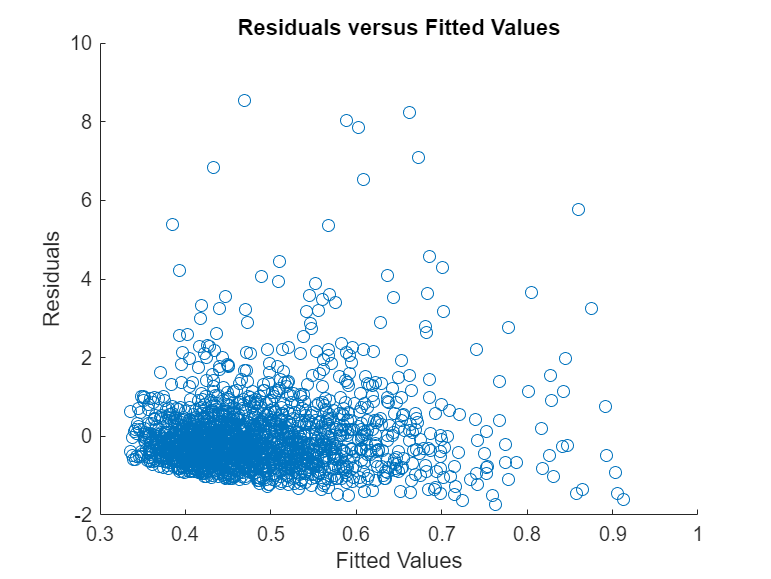

% Residuals

r = residuals(res_full,'ResidualType','Pearson');
mufit = fitted(res_full);
figure;
scatter(mufit,r);
title('Residuals versus Fitted Values');
xlabel('Fitted Values');
ylabel('Residuals');

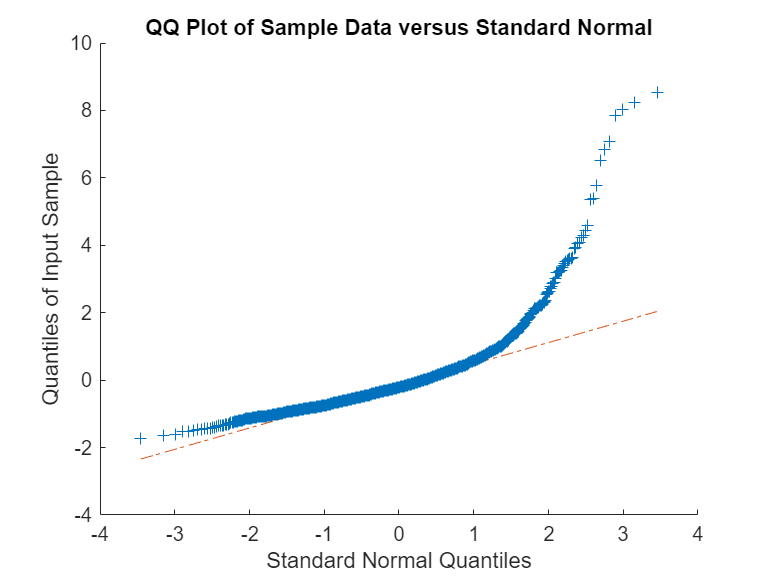


qqplot(r);

[beta, beta_SE, stats] = fixedEffects(res_full);

% Confidence level
alpha = 0.05; % 95% confidence level
t_value = tinv(1 - alpha/2, stats.DF);

beta(2:end) = beta(1) + beta(2:end);
stats.SE(2:end) = sqrt(stats.SE(1)^2 + stats.SE(2:end).^2);

% Compute Confidence Intervals
CI_fixedEffects = [beta - t_value .* stats.SE, beta + t_value .* stats.SE];

% Display results
disp('Fixed Effect Estimates and 95% Confidence Intervals:');

Fixed Effect Estimates and 95% Confidence Intervals:


table(beta, stats.SE, CI_fixedEffects(:,1), CI_fixedEffects(:,2), ...
    'VariableNames', {'Estimate', 'SE', 'Lower_95CI', 'Upper_95CI'})

ans = 4×4 table
    Estimate       SE       Lower_95CI    Upper_95CI
    ________    ________    __________    __________

     2.3336      0.06861       2.199        2.4681  
     2.5338      0.10273      2.3323        2.7352  
      2.018      0.10039      1.8211        2.2149  
     2.0475     0.098985      1.8534        2.2416  


#### The filter effect of node degree centrality

dummy_table = excluded_graph_table;
dummy_table.nodes = categorical(dummy_table.nodes);
dummy_table.PID = categorical(dummy_table.PID);
gaze_full_group_io_building_node = join(gaze_full_group_io_building, dummy_table, ...
    "LeftKeys", ["PID", "hitObjectColliderName"], ...
    "RightKeys", ["PID", "nodes"], ...
    "RightVariables", "connections");

median_gaze_full_group_io_building_node = groupsummary(gaze_full_group_io_building_node, ["PID", "hitObjectColliderName", "category", "inside", "connections"], "median", "clusterDuration");
% median_gaze_full_group_io_building_node = gaze_full_group_io_building_node
query = median_gaze_full_group_io_building_node.connections > 10;
% median_gaze_full_group_io_building_node = median_gaze_full_group_io_building_node(query, :);
median_gaze_full_group_io_building_node.is_landmark = query;

[res_full, sum_full] = fit_and_interpret_glme(median_gaze_full_group_io_building_node, "median_clusterDuration ~ connections + (1 | PID) + (1 | hitObjectColliderName)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ connections + (1 | PID) + (1 | hitObjectColliderName)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 4348.0233, BIC: 4375.5809
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
connections: Coefficient = 0.0032 (p=0.6051). Interpret based on link function reciprocal


[res_nope, sum_nope] = fit_and_interpret_glme(median_gaze_full_group_io_building_node, "median_clusterDuration ~ connections + (1 | PID)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ connections + (1 | PID)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 4823.872, BIC: 4845.9181
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
connections: Coefficient = -0.0069 (p=0.2054). Interpret based on link function reciprocal


res_full

res_full = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            1829
    Fixed effects coefficients           2
    Random effects coefficients        151
    Covariance parameters                3
    Distribution                    Gamma 
    Link                            Reciprocal
    FitMethod                       MPL   

Formula:
    median_clusterDuration ~ 1 + connections + (1 | PID) + (1 | hitObjectColliderName)

Model fit statistics:
    AIC     BIC       LogLikelihood    Deviance
    4348    4375.6    -2169            4338    

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE           tStat     DF      pValue         Lower         Upper   
    {'(Intercept)'}           2.1562     0.070453    30.605    1827    2.0356e-166         2.018      2.2944
    {'connections'}        0.0032085    0.0062048    0.51

comp_res = compare(res_full, res_nope);

r2 = calculate_nakagawa_r2(res_nope);